# Lesson 5

Written by Brenda So

## Objective

After this class, you should be able to:

- Go over debugging and publishing in MATLAB

- Have a overview idea of the z transform 

- Know how to plot pole zero plots of the z transform, and what to infer

- Know how to input a signal to the transfer function of z transform

- Know how to use the symbolic toolbox

## Overview of the z transform

The z transform converts a discrete time signal, which can be represented in real or complex numbers, into a sequence of complex exponentials. There are two key motivations of the z transform:

- By identifying the impulse response of the system we can determine how it would perform in different frequencies

- By identifying the presence of increasing or decreasing oscillations in the impulse response of a system we can determine whether the system could be stable or not

## Polynomials in MATLAB

Before we step into z transform, we should take a look at what functions are there in MATLAB to evaluate polynomials. There are 4 major functions to know about -- polyval, root/poly and conv.

## polyval

Allows you to evaluate polynomials at specified values

p = [2 -2 0 -3]     % 2x^3-2x^2 -3 

p =      2    -2     0    -3


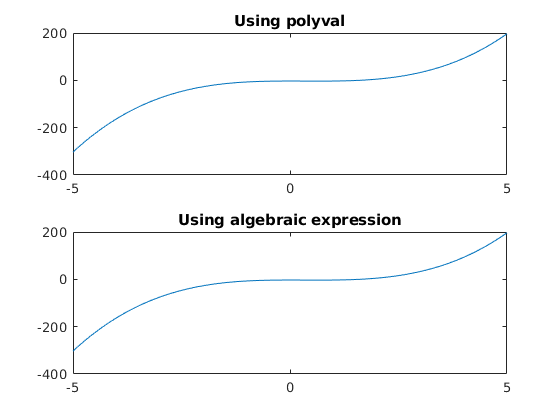

x = -5:.05:5;
a = polyval(p,x);
a2 = 2*x.^3 - 2*x.^2 - 3;
figure
subplot(2,1,1);
plot(x,a)
title('Using polyval')
hold on;
subplot(2,1,2);
plot(x,a2)
title('Using algebraic expression')

The graphs are the same!

## roots/poly

These two functions are direct opposites of one another. They allow you to find the root / coefficient of a vector of numbers

r = roots(p)

r =    1.5919 + 0.0000i
  -0.2960 + 0.9245i
  -0.2960 - 0.9245i


p1 = poly(r)

p1 =     1.0000   -1.0000   -0.0000   -1.5000


## conv

If Fontaine's talked about it, you mostly heard of convolution when you multiply in the frequency domain, i.e. when you feed a signal through a system, you need to multiply in the frequency domain. It is also used when you MULTIPLY TWO POLYNOMIALS TOGETHER!!!

a = [1 2 -3 4];      
b = [5 0 3 -2];      
p2 = conv(a,b)       % Use convolution

p2 =      5    10   -12    24   -13    18    -8


## Z transform

One of the things we usually evaluate in the z transform is the pole zero plot, since the pz plot can talk about stability and causality in different regions of convergence. Let us just look at one simple example of a pole zero plot

## NOTE TO TUTOR

The pedagogical value of this part is to first show one big pz plot, explain how to identify regions of convergence, stability and causality, and later on display different pz plot to visualize stability and causality

## Z transform - generate a pole zero plot

There are multiple ways to generate the pole zero plot. If you are interested, you should look up tf2zp (and its inverse, zp2tf), pzplot, etc. We are going to introduce the most simple function -- zplane. In the example, b1 and a1 and coefficients of the numerator and denominator, i.e, the transfer function. The Transfer function can be interpreted as the ratio between output (denominator) and input (numerator). At home, you are going to explore how to use tf2zp

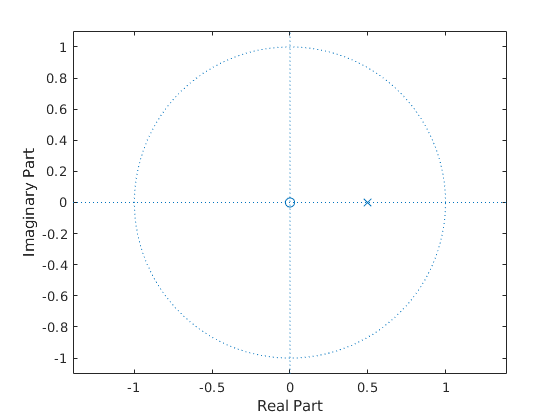

b1 = [1];       % numerator
a1 = [1 -0.5];  % denominator
figure;
zplane(b1, a1)

## BE CAREFUL!

If the input vectors are COLUMN vectors, they would be interpreted as poles and zeros, and if they are ROW vectors, they would be interpreted as Coefficients of the transfer function. 

## BE CAREFUL!

zplane takes negative power coefficients, while tf2zp (the one where used in the homework) uses positive power coefficients. 

## Z transform - More examples!

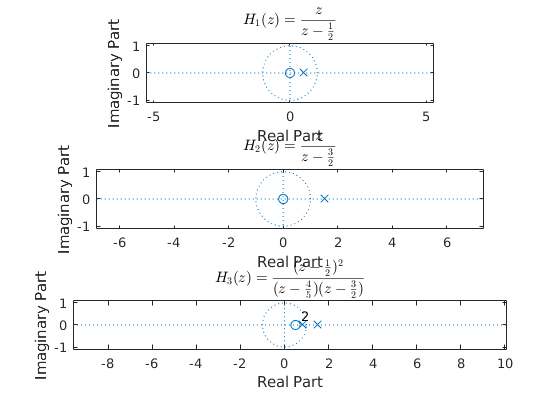

b2 = [1];
a2 = [1 -1.5];
b3 = [1 -1 0.25];
a3 = [1 -23/10 1.2];

% Example 1 : One pole, outer region is stable and causal
figure;
subplot(3,1,1);
zplane(b1,a1);
title('$$H_1(z)=\frac{z}{z-\frac{1}{2}}$$','interpreter','latex')
% Example 2 : One pole, outer region is causal but not stable, inner region
% is stable but not causal
subplot(3,1,2);
zplane(b2,a2);
title('$$H_2(z)=\frac{z}{z-\frac{3}{2}}$$','interpreter','latex')
% Example 3 : Two poles, outer region is causal, middle region is stable
subplot(3,1,3);
zplane(b3,a3);
title('$$H_3(z)=\frac{(z-\frac{1}{2})^2}{(z-\frac{4}{5})(z-\frac{3}{2})}$$',...
    'interpreter','latex')

## On Stability and Causality

The system is stable iff the region contains the unit circle The system is causal iff the region contains infinity If there is an infinity to the pole, then it's not stable If all the poles are in the unit circle, then the system could be both stable and causal

## Z transform - Impulse Response

The impulse response is useful because the fourier transform of the impulse response allows us to evaluate what is going to happen at different frequencies.

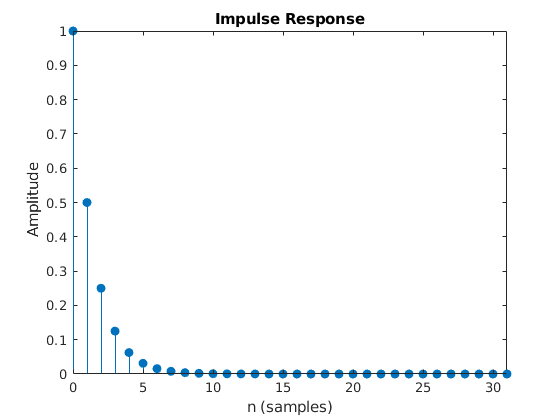

[h1,t] = impz(b1,a1,8);     % h is the IMPULSE RESPONSE
figure;
impz(b1,a1,32);            % for visualization

In DSP, you will learn how to go from impulse response to frequency response, but for now, if you want to know the frequency response, just take the short cut and use freqz ;)

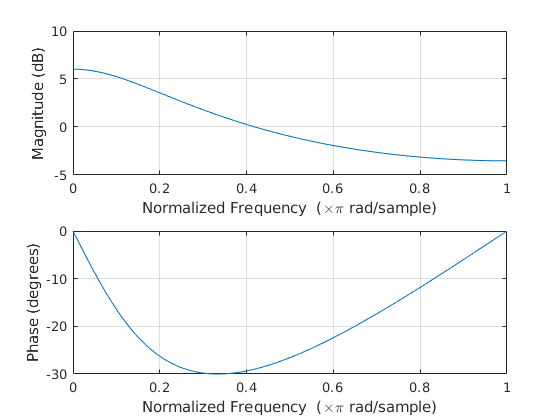

figure
freqz(b1,a1);

## Z transform - Convolution

After you obtain the impulse response, you can see what happens to the signal by convolving the impulse response with a signal

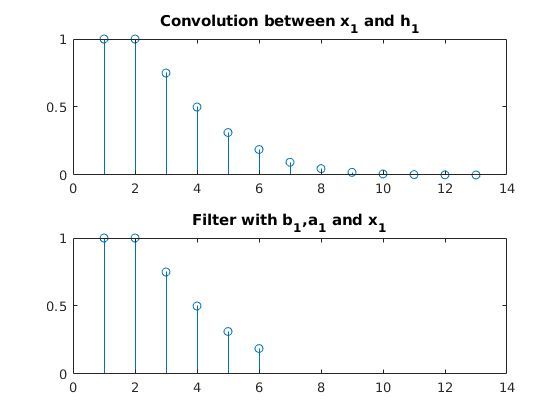

n = 0:1:5;
x1 = (1/2).^n;
y1 = conv(x1,h1);
figure;
subplot(2,1,1);
stem(y1);
title('Convolution between x_1 and h_1');
subplot(2,1,2);
y2 = filter(b1,a1,x1);
stem(y2);
title('Filter with b_1,a_1 and x_1');
xlim([0 14]);

## Symbolic Toolbox

The symbolic toolbox is useful if you want an exact expression of a function. In MATLAB, we often numerically evaluate functions, hence the symbolic toolbox could be useful in providing analytic solutions (when it can)

% Differentiation
syms x y z
v = x^2 + 16*x + 5;
dvdx = diff(v)
dvdx_3 = subs(v, x,3)
% Integration
V = int(v)

% Integration with limits
syms a b
Vab = int(v,a,b);
V01 = int(v,0,1);

% Partial differentiation
w = -x^3 + x^2 + 3*y + 25*sin(x*y);
dwdx = diff(w,x);
dwdy = diff(w,y);

% third order derivative w.r.t. x
dw3dx3 = diff(w,x,3);

% solve
syms c
res = solve(c^2 - c + 1 == 4*c + 3);

%z transform
syms a n x
f = a^n;
ztrans(f, x)

% Other functions:
% simplify (sometimes...)
% Laplace, fourier, jacobian, curl, divergence...
% The symbolic toolbox is massive and powerful

% Can even handle matrices!
syms m
n = 4;
A = m.^((0:n)'*(0:n));
D = diff(log(A));

## BE CAREFUL!

Although we have used diff before, the diff used previously and the diff used in this context is not the same. Type 'help diff' and 'help sym/diff' if you want to learn more about it!